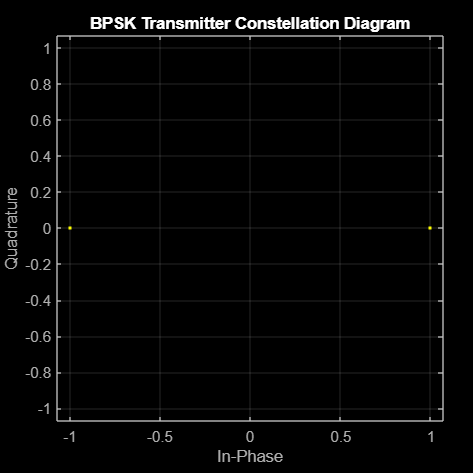

% Source encoder and Channel Encoder of a given text
text    = 'BABAAAAABCCBBBCAADAADBDAAABBADAACAAD';
N       = 3;
encodedText = sourceEncoder(text);
encodedBits = channelEncoder(encodedText, N);

% BPSK Modulation
M = 2;
bpskModulated = pskmod(encodedBits, M, pi);

scatterplot(bpskModulated);
title('BPSK Transmitter Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;

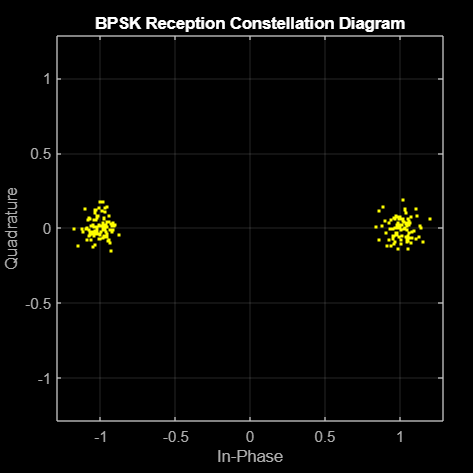

rxSignal = awgn(bpskModulated,20);
scatterplot(rxSignal)
title('BPSK Reception Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;